# 2223-MA378 Lab 3: Gaussian Quadrature

clear;

## 1. Numerical Integration 

(FYI, MATLAB has some built-in functions for numerical integration, but we'll are interested in writing our own).

Given a function $f(x)$, we want to approximate $\int_a^bf(x)dx$ for some range $[a,b]$. We've learned about two ways to do this.

### Newton-Cotes methods

For a Newton-Cotes method, $Q_n(\cdot)$, we set $x$ to be the set of $n+1$ equally spaced points on the interval $[a,b]$ that include the two end points. These are called the *quadrature points*. We then let $q$ be a set of $n+1$ quadrature wieghts so that $Q_n(p_n)=\int_a^b p_n(x)dx$, for any $p_n$ that is a polynomial of degreee $n$. (Review notes from Section 3.2 to see how these points are calculated). Then we compute $Q_n(f) = \sum_{i=0}^nq_if(x_i)$

Here are some examples, and how to use them.

### Test Problem Data

In the example, we'll approximate the integral of $f(x)=\log(2+x)$, on $[a,b]=[-1,1]$. The correct answer is $3\log(3)-2$.

a=-1; b=1;
f = @(x)log(2+x);
TrueInt = 3*log(3)-2;

#### Trapezium Rule

For the Trapexium Rule, denoted, $Q_1(\cdot)$ we have

x = [a, b];
q = [1, 1];

We could compute this as q(1)*f(x(1)) + q(2)*f(x(2)). However, the following code works for any pair of vectors $x%$ and $q$, so long as they are the same length.

Q1 = sum(q.*f(x));
Q1Error = abs(TrueInt - Q1);
fprintf('Q1: Estimate = %8.6f, Error = %8.3e\n', Q1, Q1Error);

Q1: Estimate = 1.098612, Error = 1.972e-01


#### Simpson's Rule

n=2;
x = linspace(a,b,n+1);
q = [1,4,1]/3;
Q2 = sum(q.*f(x));
Q2Error = abs(TrueInt - Q2);
fprintf('Q%d: Estimate = %8.6f, Error = %8.3e\n', n, Q2, Q2Error);

Q2: Estimate = 1.290400, Error = 5.437e-03


#### Three point Newton-Cotes

The 3-point scheme has weights: $\{1/4, 3/4, 3/4, 1/4\}$. Here is its estimate

n=3;
x = linspace(a,b,n+1);
q = [1,3,3,1]/4;
Q3 = sum(q.*f(x));
Q3Error = abs(TrueInt - Q3);
fprintf('Q%d: Estimate = %8.6f, Error = %8.3e\n', n, Q3, Q3Error);

Q3: Estimate = 1.293246, Error = 2.591e-03


### Deriving n-point Newton-Cotes

In general, a Newton-Cotes method may be constructed by first choosing the points and then computing $q_k = \int_a^b L_k(x)dx$ here $L_k$ is the Lagrange Polynomial associated with the point $x_k$. In the next section, we'll see how to compute that.

## 2. Polynomials in MATLAB

In MATLAB, a polynomial is represented as a vector:

- If the vector is called $p$, then the degree of the polynomial is `n=length(p)-1`.

- p(1) is the coefficent of $x^n$, p(2) is the coefficient of $x^{n-1}$, ..., `p(n+1)`is the coefficient of $x^0=1$. In general, $p(k)$ is the coefficient of $x^{n-k+1{$.

Examples:

- The vector for any monic polynomial will has 1 as its first entry.

- The vector for $p_3=x^3-1$ is p=[1,0,-1]. 

- p=[5,-4,3,-2] is the vector for $p_4=5x^3 -4x^2 + 3x -2$.

MATLAB has several useful functions for working with polynomials. Here are some we'll use in this lab

### polyval()

Given vectors $p$ and $x$, the function call polyval(p,x) returns the values of the polynomial represented by $p$ at the points in $x$.

Example: let's check that $x^2+x-6=(x-2)(x+3)$ is zero at $x=-3$ and $x=2$. 

p2=[1,1,-6]

p2 =      1     1    -6


polyval(p2,[-3, 2])

ans =      0     0


`polyval()` is particularly useful for plotting. To plot a polynomial represented by the vector $p$ on the interval $[a,b]$, do something like this:

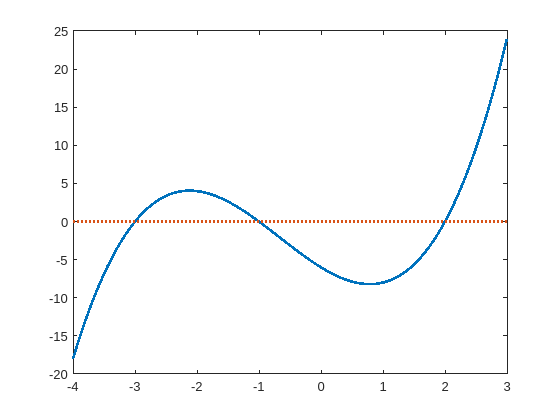

p3=[1,2,-5,-6]; % reps x^3+2x^2-5x-6
a=-4; b=3; % change these to anything you like.
x=linspace(a,b,100); % vector with 100 points in [a,b]
plot(x, polyval(p3,x), x,x*0, ':', 'LineWidth',2)

### roots()

Given a vector $p$ that represents a polynomial, the roots() function returns its roots. In the previous example, the plot suggests $p_3$ has roots at x=-3, $x=-1$, and $x=2$. Let's check:

roots(p3)

ans =     2.0000
   -3.0000
   -1.0000


### conv()

The `conv()` function can be used to multiply polynomials.  The name comes from an operation on vectors called convolution, which is equivalent to polynomial interpolation. To try it out, let's recall that the ploynomial $p_1(x)=x-s$ is the polynomial of degree 1 with a zero at $x=s$. In MATLAB, we could represent it as `p1=[1,-s]`. In an earlier example we had a polynomial  $x^2+x-6=(x-2)(x+3)$. To make this using `conv()`:

p2=conv([1,2],[1,-3])

p2 =      1    -1    -6


In another example, we claimed $x^3+2x^2-5x-6$ had roots at $

p3 = 1; % Start with degree zero
p3 = conv(p3, [1,3]); % multiply by x-3
p3 = conv(p3, [1,1]); % multiply by x-3
p3 = conv(p3, [1,-2]); % multiply by x-3
disp(p3)

     1     2    -5    -6



### polyint()

The `polyint()` function returns the coefficients for the polynomial that is the antidervative of the given one, assuming a constant of integration of $0$. For example, we know that $\int_a^b  x^3 +2x^2 -5x-6 dx = \frac{1}{4}x^4 + \frac{2}{3}x^3 -\frac{5}{2}x^2 -6x+C$. Let's check:

g=polyint(p3)

g =     0.2500    0.6667   -2.5000   -6.0000         0


In numerical integration, we are usually interested in computing definite integrals. To compute $\int_{-1}^1 p_3(x) dx$ first set $g$ to be the antiderivative of $p_3$, and then use `polyval() to compute `$g(-1)$ and $g(1$). Subtract the first from the second to get the desired value. 

polyval(polyint(p3),1)-polyval(polyint(p3),-1)

ans = -10.6667

This can also be done with the `diff()` function:

diff(polyval(polyint(p3),[-1,1]))

ans = -10.6667

Because we'll often have to compute definite integrals of polynomials, to make the code more readable, there is a function at the end of this script, `PolyDefInt(p,a,b)`, that returns $\int_a^b p(x)dx$.

## 3. Deriving Newton Cotes Rules

We now have all the tools needed to compute quadrature weights for Newton-Cotes methods. As an example, let's reproduce that $4$-point scheme.

n = 3;
a = -1; b = 1;
x = linspace(a,b,n+1);
q = zeros(1,n+1); % vector where we will store the weights

Next we define the weights as inetgrals of the Lagrange polynomials: $L_1 = \prod_{k=0, k \neq 1}^{n} \frac{x-x_k}{x_i-x_k}$. In the following, take care to note that MATLAB indexes from 1, and not 0.

for i=1:n+1
   Li = 1; % will use conv() to build the Lagrange polynomial
   for k=1:n+1
      if (k ~= i)
         Li = conv(Li, [1,-x(k)])/(x(i)-x(k));
      end
   end
   q(i) = PolyDefInt(Li,a,b);
end
disp(q) % output values of q

    0.2500    0.7500    0.7500    0.2500



You should check that these are the same values as use above. Sometimes, it can be helpful to look at rational expressions for these numbers:

rat(q)

ans = 4×10 char array
    '0 + 1/(4) '
    '1 + 1/(-4)'
    '1 + 1/(-4)'
    '0 + 1/(4) '


Because we'll often need to compute the Lagrange Polynomials for a set of points, there is a function below called `LagrangePoly(x, i)` which returns the vector for $L_i$ where the interpolation points are in the vector $x$.

## 4. Gaussian Quadrature

The Gaussian Quadrature method, $G_n(\cdot)$, is based on choosing the weights and the points to optimise the precision of the method. We've learned in class the that trick to computing these values involves working with sequences of orthogonal monic polynomials. 

### Sequences of monic orthogonal polynomials

Review the notes from Section 3.5, and especially Theorem 5.11. See [https://www.niallmadden.ie/2223-MA378/3-5-OrthogonalPolynomials.pdf.](https://www.niallmadden.ie/2223-MA378/3-5-OrthogonalPolynomials.pdf.)  Because we are using MATLAB, we have to change the notation: we'll represent $\tilde p_k$ as `p{k+1}`, since MATLAB indexes from zero.

To use the algorithm, we need to complete numerous inner products. Do simplify the code, somewhat, there is a function at the end of this script called `IP()`. It computes $IP(p,q) = \int_{-1}^1 p(x)q(x)dx$ where $p$ and $q$ are vectors representing polynomials. 

Start bt setting $\tilde p_1=1$

p{1} = 1; % this is what we used call p0. But MATLAB indexes from 1, unfortunately.

The we compute $\tilde p_2 = x - \alpha$.

alpha = IP( conv([1,0], p{1}),p{1})/IP(p{1},p{1}); % Note [1,0] is the polynomial 'x'.
p{2} = [1,-alpha];

After thak we use $\tilde p_{n+1}(x) = (x-\alpha)\tilde p_n(x) -\beta \tilde p_{n-1}(x)$.

n = 2;
alpha = IP( conv([1,0], p{n}),p{n})/IP(p{n},p{n}); 
beta  = IP( conv([1,0], p{n}),p{n-1})/IP(p{n-1},p{n-1}); 
p{n+1} = conv([1,-alpha], p{n}) - beta*[0,0,p{n-1}]; % Padded p{n-1} with 2 zeros, because we can only add poly/vectors of the same degree/length

From Example 5.12 of section 3.5.4, we know that, with $a=-1$, and $b=1$, we should get the first three polynomials to be $1$, $x$ and $x^2-1/3$. Furthermore, the roots of $x^2-1/3$, are the quadrature points for $G_1(x)$, i.e., $x_0 = -\frac{1}{\sqrt{3}}$ and $x_1 = \frac{1}{\sqrt{3}$. Let's check:

x2=roots(p{3})'  % transposed to row vector

x2 =     0.5774   -0.5774


### Gaussian Quadrature Weights

The weights are computed in the same was as for Newton-Cotes: given a set of points, compute the Lagrange polynomials for each of these. Their interals on $[a,b]$ are the weights.

L1 = LagrangePoly(x2,1);
w2(1) = PolyDefInt(L1,-1,1);
L2 = LagrangePoly(x2,2);
w2(2) = PolyDefInt(L2,-1,1);
disp(w2)

    1.0000    1.0000



Now we can apply the method. The code is essentially the same as for Newton-Cotes.

n = 1;
x = roots(p{n+1})'; % make sure that p{n+1} has been computed above.
w = zeros(1,n); % 
for i=1:n
   w(i) = PolyDefInt(LagrangePoly(x, i),-1,1);
end
G2 = sum(w.*f(x));
G2Error = abs(TrueInt - G2);
fprintf('G2: Estimate = %8.6f, Error = %8.3e\n', G2, G2Error);

G2: Estimate = 1.386294, Error = 9.046e-02


## 5. Your Tasks

- Create a new (blank) live script. Add your name, ID number and email address at the start.  (If you prefer, just delete all the unneeded stuff from this script).

- Copy the test problem data (values of $a$, $b$, $f$ and TrueInt) from Section 1.

- Copy the functions from Section 6 (Functions) to the **end** of your script.

- Write a piece of code that derives and implements the 5-point Newton-Cotes method, and tests in when integrating $f(x)=\log(2+x)$. The test should include reporting the error.

- Write a piece of code that derives and implements the 3-point and 4-point Gaussian methods, and tests them when integrating $f(x)$. The tests should include reporting the error.

## 6. Functions

### IntPoly()

`PolyDefInt(p,a,b) `returns $\int_a^b p(x)dx$

function int_ans = PolyDefInt(p,a,b)
g = polyint(p);
int_ans = polyval(g,b)-polyval(g,a);
end

### LagrangePoly()

function Li = LagrangePoly(x,i)
n = length(x)-1;
Li = 1; % will use conv() to build the Lagrange polynomial
for k=1:n+1
   if (k ~= i)
      Li = conv(Li, [1,-x(k)])/(x(i)-x(k));
   end
end
end

### IP()

Compute the inner product of two polynomials on $[-1,1]$

function v = IP(p,q)
r = conv(p,q);
v = PolyDefInt(r,-1,1);
end
